# RBE502 - Fall 2020 - Homework 1 - Part 2 - Case Study I

clc; clear; close all;

m = 1;          % Mass of the block [kg]
b = 2;          % Damping coefficient [Ns/m]
k = 4;          % Spring stiffness [N/m]

t0 = 0;         % Simulation start time
tf = 10;        % Simulation finish time

y0 = 0;         % y0 = y(t0)
v0 = 0;         % v0 = dy/dt(t0)

% r = 1;
% dr = 0;
r = @(t) cos(t);          % Reference (desired) input
dr = @(t) -sin(t);         % Derivative of the reference input with respect to time


phi = @(x,kp,ki,kd, t) kp*(r(t) - x(1)) + ki*x(3) + kd*(dr(t) - x(2)); 

f = @(t, x, u)[ x(2); (u - b*x(2) - k*x(1))/m; r(t) - x(1)];


x0 = [y0; v0; r(t0) - y0];
tspan = [t0, tf];

## Case Study 1: Varying kp, fixed ki and kd

kp = 10;
ki = [2, 5, 10];
kd = 0;

axes; hold on; box on; grid on;

for gain = ki
    [t,x] = ode45(@(t,x)f(t,x,phi(x,kp,gain,kd, t)), tspan, x0);
    e = r(t) - x(:,1);
    
    J = trapz(t,abs(e));
    
    plot(t,x(:,1),'LineWidth',1.5);
    
    
    fprintf('kp = %2d, tf = %d, e(tf) = %.4f, J = %.4f\n',...
        gain, tf, e(end,1), J);
end

kp =  2, tf = 10, e(tf) = -0.1432, J = 2.3883
kp =  5, tf = 10, e(tf) = -0.0572, J = 2.5610
kp = 10, tf = 10, e(tf) = 0.0317, J = 2.6428


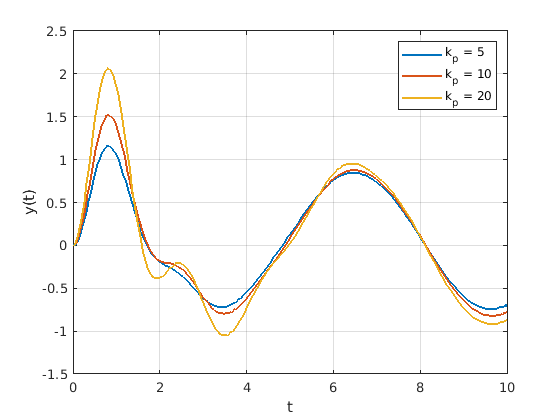


% plot(tspan,[r r],'k');
xlabel('t'); ylabel('y(t)');
legend('k_p = 5','k_p = 10', 'k_p = 20','r');